## 1. Naloga

y = evalin(symengine, 'solve(rec(y(k)=y(k-1)+y(k-2),y(k),{y(0)=1,y(1)=1}))')

k=1:1:10

k =      1     2     3     4     5     6     7     8     9    10


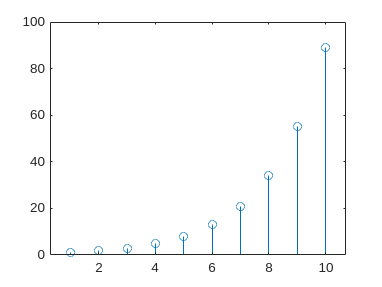

res = eval(y);
stem(k,res)

## 2. Naloga

y = evalin(symengine, 'solve(rec(y(k)=y(k-1)+y(k-2),y(k),{y(0)=3,y(4)=3}))')

$$y = \left\{{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{k}\,\left(\frac{\sqrt{5}}{2}+\frac{3}{2}\right)+\frac{\sqrt{5}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{k}\,\left(3\,\sqrt{5}-5\right)}{10}\right\}$$


k=1:1:10

k =      1     2     3     4     5     6     7     8     9    10


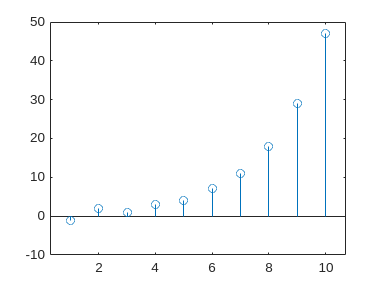

res = eval(y);
stem(k,res)

## 3. Naloga a

## Symbolic math:

syms z k
G_z = (z^2)/(z^2-z-1);
h_k = iztrans(G_z, z, k); 
disp('The impulse response h(k) is:');

The impulse response h(k) is:


disp(h_k);

$$\begin{array}{l} \frac{2\,{\left(-1\right)}^{k}\,\cos\left(k\,\left(\frac{\pi }{2}+\mathrm{asin}\left(\frac{1}{2}\,\mathrm{i}\right)\right)\right)}{{\mathrm{i}}^{k}}-\frac{\sigma_{1}\,{\left(-1\right)}^{k}\,\sqrt{5}\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{k-1}}{5}+\frac{\sigma_{1}\,{\left(-1\right)}^{k}\,\sqrt{5}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{k-1}}{5}\\ \mathrm{where}\\ \sigma_{1}={\left(-1\right)}^{1-k} \end{array}$$

## Control system:

G_z = tf([1, 0, 0],[1, -1, -1])


G_z =
 
      s^2
  -----------
  s^2 - s - 1
 
Continuous-time transfer function.
Model Properties


disp('The impulse response G(z) is:');

The impulse response G(z) is:


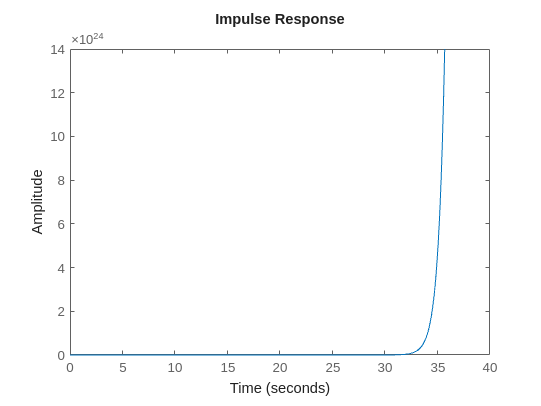

impulse(G_z)

## 3. Naloga b

## Symbolic math:

syms z k
G_z = (z^2)/(z^2-z-1);
U_z = (z)/(z-1);
Y_z = G_z * U_z

$$Y\_z = -\frac{z^{3}}{\left(z-1\right)\,\left(-z^{2}+z+1\right)}$$

y_k = iztrans(Y_z, z, k); 
disp('The step response y(k) is:');

The step response y(k) is:


disp(y_k);

$$\begin{array}{l} \frac{6\,{\left(-1\right)}^{k}\,\cos\left(k\,\left(\frac{\pi }{2}+\mathrm{asin}\left(\frac{1}{2}\,\mathrm{i}\right)\right)\right)}{{\mathrm{i}}^{k}}-\frac{4\,\sigma_{1}\,{\left(-1\right)}^{k}\,\sqrt{5}\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{k-1}}{5}+\frac{4\,\sigma_{1}\,{\left(-1\right)}^{k}\,\sqrt{5}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{k-1}}{5}-1\\ \mathrm{where}\\ \sigma_{1}={\left(-1\right)}^{1-k} \end{array}$$

## Control system:

G_z = tf([1,0,0],[1,-1,-1],-1)


G_z =
 
      z^2
  -----------
  z^2 - z - 1
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


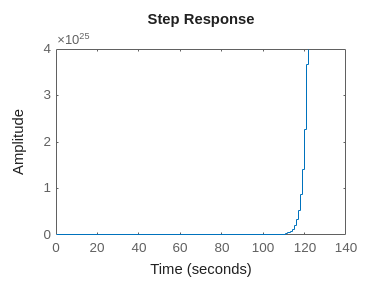

disp('The step response G(z) is:');
step(G_z)

## 4. Naloga

a = 1

a = 1

G_z = tf([1, 0.95],[1, (a+0.9), (0.9*a)],1);

figure;
a = 1

a = 1

step(G_z,30);
hold on;
a = 0.9

a = 0.9000

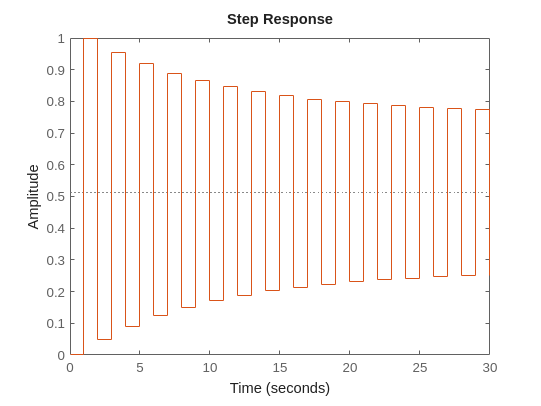

step(G_z,30);


figure;
a=1

a = 1

impulse(G_z,30)
hold on;
a = 0.9

a = 0.9000

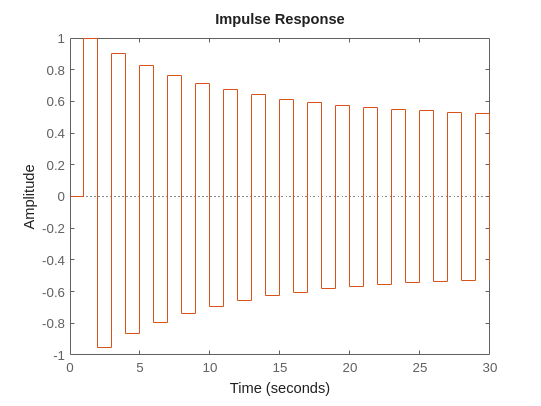

impulse(G_z,30)

## 5. Naloga

a = 0.9

a = 0.9000

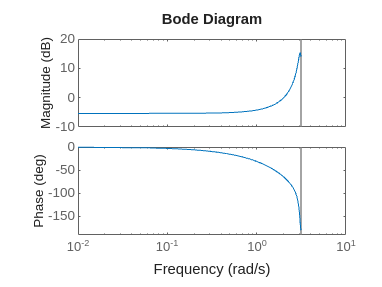

G_z = tf([1, 0.95],[1, (a+0.9), (0.9*a)], 1);
figure;
bode(G_z)

## 6. Naloga

G_z = tf([1, 0, 1],[2,0,0],1)


G_z =
 
  z^2 + 1
  -------
   2 z^2
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


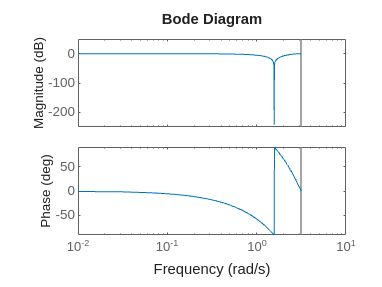

figure;
bode(G_z)

## 7. Naloga

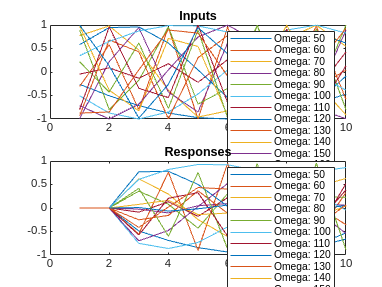

T = 1;
N = 10;
k = 1:N;
u_k = zeros(1,N);
y_k = zeros(1,N);

figure;
for omega=50:10:200;
    u_k = sin(omega * k * T);
    for n = 3:N;
        y_k(n) = 0.5*(u_k(n)+u_k(n-2));
    end;
    subplot(2,1,1);
    plot(k, u_k, 'DisplayName',['Omega: ', num2str(omega)]);
    hold on;
    title("Inputs");
    legend('show');

    subplot(2,1,2)
    plot(k, y_k, 'DisplayName',['Omega: ', num2str(omega)])
    hold on;
    title('Responses');
    legend('show');
end;